# Schroer-Ott Pass Targeting: Reconciled Walkthrough

This Live Script is the principal explanatory document for the reconciled Schroer-Ott implementation in this folder. It replicates C. G. Schroer and E. Ott, "Targeting in Hamiltonian systems that have mixed regular/chaotic phase spaces", Chaos 7, 512-519 (1997), for the normalized standard map at $k = 1.25$ with control bound $|\delta_n| \le 0.003$.

The verified so_* files remain the computational foundation. This document calls them in a transparent order and shows the formulation, the numerical construction, the three case studies, the ensemble and noise validations, the diagnostic figures and the limitations inline.

What this folder reconciles:

- The targeting engine is taken unchanged from the "fundamental" folder. so_resolve_connection, so_build_curve, so_refine_intersection, so_enumerate_periodic_orbits, so_connection_better and so_switch_candidate_better are byte-for-byte copies. Nothing in the search for a control was altered.

- Added from the other folder, and extended: the uncontrolled phase portrait underneath every phase-space figure, and per-control execution records that make the kicks drawable and the noise replay possible.

- New here: three source/target geometries whose routes differ in kind, a 50-source ensemble, and a swept additive-noise validation.

Methodological status. The route is a rotation-ordered route through the direct-hyperbolic periodic-orbit proxies that lie between source and target in the transport coordinate. The diagnostic manifolds are displayed a posteriori; they do not determine route acceptance, switching or success. This remains a numerically safeguarded implementation rather than a complete automatic reconstruction of the paper: Section "Interpretation and Limitations" states precisely what is and is not established.

## Reproducible Project Setup

Everything below runs from this folder. No toolboxes are required; the helpers so_interquartile_range and so_parse_options exist precisely so that the Statistics Toolbox and inputParser are not needed.

clearvars;
close all;
clc;

% Locate this folder whether the script is run from the Live Editor, from
% the command line, or headless.
projectPath = '';
try
    projectPath = fileparts(matlab.desktop.editor.getActiveFilename);
catch
end
if isempty(projectPath)
    projectPath = fileparts(which('so_reconciled_config'));
end
if isempty(projectPath)
    projectPath = pwd;
end
cd(projectPath);
addpath(projectPath);

cfg = so_reconciled_config();
rng(cfg.randomSeed, 'twister');

setupTable = table(string(projectPath), string(version), string(computer), ...
    'VariableNames', {'ProjectPath', 'MATLABVersion', 'Platform'});
disp(setupTable);

                                          ProjectPath                                                     MATLABVersion               Platform 
    ________________________________________________________________________________________    __________________________________    _________

    "C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\schroer_ott_reconciled"    "26.1.0.3276743 (R2026a) Update 3"    "PCWIN64"



## Numerical Configuration

One configuration function holds every number that matters. The geometry fields are overridden per case by so_case_config; everything else is shared, so the three case studies differ only in where they start, where they are going, and how many iterations they are allowed.

configurationTable = table( ...
    cfg.k, cfg.controlAmplitude, cfg.proxyTargetRadius, ...
    cfg.orbit.minPeriod, cfg.orbit.maxPeriod, ...
    cfg.curve.maxGapFraction, cfg.curve.midpointToleranceFraction, ...
    cfg.curve.maxPoints, cfg.intersectionTolerance, ...
    'VariableNames', {'k', 'controlAmplitude', 'proxyRadius', ...
    'minPeriod', 'maxPeriod', 'maxGapFraction', 'midpointTolFraction', ...
    'maxCurvePoints', 'intersectionTol'});
disp(configurationTable);

     k      controlAmplitude    proxyRadius    minPeriod    maxPeriod    maxGapFraction    midpointTolFraction    maxCurvePoints    intersectionTol
    ____    ________________    ___________    _________    _________    ______________    ___________________    ______________    _______________

    1.25         0.003             0.03            2            5             0.12                0.06                1e+05              1e-09     



## Standard-Map Formulation on the Lifted Cylinder

Equation (2) of the paper, written in the lift where $x$ may wind and $y$ is the unbounded transport coordinate:


$$y_{n+1} = y_n - \frac{k}{2\pi}\sin(2\pi x_n) + \delta_n, \qquad x_{n+1} = x_n + y_{n+1}$$


The control $\delta_n$ is an impulsive kick applied to the momentum $y$ only, bounded by $|\delta_n| \le 0.003$ exactly as in the paper. Working on the cylinder $S^1 \times \mathbb{R}$ rather than the torus is deliberate: $x$ is periodic and wrapped, $y$ is never wrapped, so a transfer that climbs through several resonances is a monotone motion in $y$ rather than an ambiguous one modulo 1.

For $k > k_c \approx 0.971635$ the chaotic region is connected and extends over the whole $y$ axis, so the target is reachable in principle. It is the slowness of the natural transport, not its impossibility, that the method attacks.

The map is area preserving, $\det DF = 1$, which the self-checks assert directly. The inverse used for backward iteration is exact, not a numerical inversion:


$$x_{n} = x_{n+1} - y_{n+1}, \qquad y_{n} = y_{n+1} + \frac{k}{2\pi}\sin(2\pi x_{n})$$


rng(7, 'twister');
z = [rand(1, 500); 2 * rand(1, 500) - 0.5];
roundTripError = max(vecnorm(so_standard_map_inverse_lifted( ...
    so_standard_map_lifted(z, cfg), cfg) - z));

jacobianError = 0;
for i = 1:size(z, 2)
    jacobianError = max(jacobianError, abs(det(so_jacobian(z(:, i), cfg)) - 1));
end

mapValidation = table(roundTripError, jacobianError, ...
    'VariableNames', {'InverseRoundTripError', 'MaxAreaDefect'});
disp(mapValidation);

    InverseRoundTripError    MaxAreaDefect
    _____________________    _____________

         4.9651e-16           4.4409e-16  



## The Map Underneath Every Figure

Every phase-space figure in this build is drawn on top of the uncontrolled phase portrait. This is the main presentational change from the fundamental folder, and it is not decoration.

The argument of the paper is geometric: resonances form barriers to transport, the overlaps between neighbouring resonances form passes, and the controlled orbit is steered from pass to pass. On an empty axis a reader cannot see whether a plotted route does anything of the kind. With the portrait underneath, the proxy balls visibly sit on the hyperbolic orbits that bound each resonance, and the controlled trajectory visibly crosses from one resonance to the next.

so_phase_portrait iterates a grid of seeds under the uncontrolled map and memoises the result for the session. so_plot_phase_background draws it as a single line object carrying dot markers; scatter would build one graphics primitive per point and take minutes for the same picture.

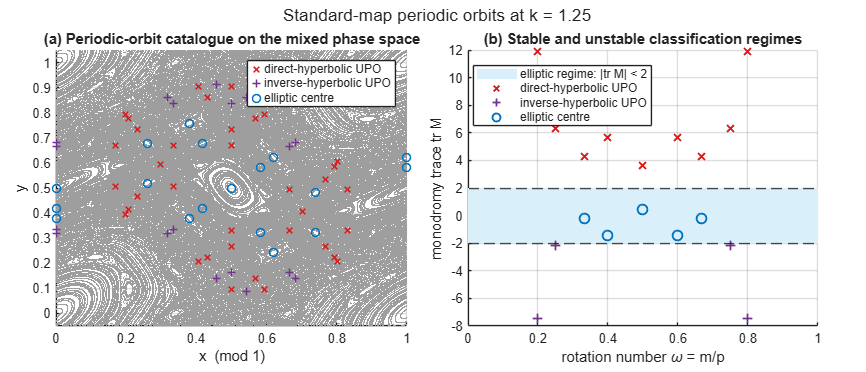

catalogue = so_enumerate_periodic_orbits(cfg);
plot_upo_catalogue_and_stability(catalogue, cfg);

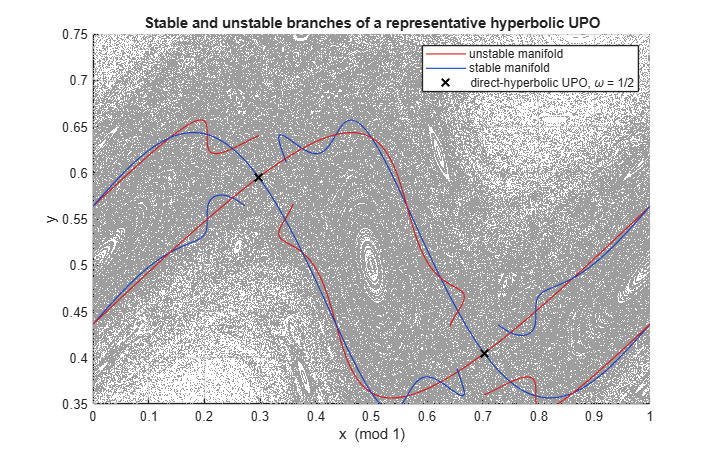

plot_representative_manifolds(catalogue, cfg);


% The first figure distinguishes direct-hyperbolic, inverse-hyperbolic and
% elliptic chains on the uncontrolled phase portrait, then places every
% chain against the stability boundaries tr(M) = +/-2.
%
% The second figure draws the stable and unstable branches of the direct-
% hyperbolic omega = 1/2 chain. Unstable branches are iterated forward;
% stable branches are iterated backward. The same branch construction is
% applied to every route chain in the later case-study figures.
%
% These figures are diagnostic. They explain the phase-space geometry but
% do not define route acceptance, switching or target containment.
%
% The catalogue is retained in the workspace for the periodic-orbit table,
% route construction and all three targeting cases below.

## Source, Target and Control Representation

Three kinds of set appear in the calculation, and each is represented by its boundary curve together with a containment predicate, so that the same forward-backward machinery applies to all of them:

- The admissible control segment, a vertical segment of length $2\delta$ through the current state, parameterised by the control value itself. This is so_make_control_component.

- A proxy target, a ball of radius 0.030 around one phase point of a direct-hyperbolic periodic orbit. This is so_make_circle_component, and it is the paper's own choice: "As the target region in every resonance, we choose a small ball around the unstable periodic orbit that is associated with it."

- The final target, a rectangle on the cylinder. This is so_make_rectangle_component, and containment is periodic in $x$ but not in $y$.

Because the control acts on $y$ alone, the reachable set from a given state in one step is a curve, not an area. That is the whole reason a forward-backward construction is needed rather than a direct solve.

[caseCfg, caseMeta] = so_case_config('diagonal');
sourceTargetTable = table( ...
    string(caseCfg.caseName), ...
    caseMeta.sourceCentre(1), caseMeta.sourceCentre(2), ...
    caseMeta.targetCentre(1), caseMeta.targetCentre(2), ...
    caseCfg.controlAmplitude, 2 * caseCfg.controlAmplitude, ...
    'VariableNames', {'Case', 'SourceX', 'SourceY', 'TargetX', 'TargetY', ...
    'ControlBound', 'SegmentLength'});
disp(sourceTargetTable);

       Case       SourceX    SourceY    TargetX    TargetY    ControlBound    SegmentLength
    __________    _______    _______    _______    _______    ____________    _____________

    "diagonal"     0.665       0.5       0.23       0.73         0.003            0.006    



## Periodic-Orbit Search

Chains are found by Newton's method on the lifted period condition


$$F^{\,p}(z) - z - (m, 0)^{\mathsf{T}} = 0$$


seeded on a grid in $x$ and on offsets around $y = m/p$, with damped line search, then deduplicated up to cyclic shift and filtered for lower-period solutions. The rotation number $\omega = m/p$ labels the resonance the chain belongs to.

disp(catalogue.byOmega);

        id         period    winding     omega      trace     residue     absResidue     residual        classification       samePMCount
    ___________    ______    _______    _______    _______    ________    __________    __________    ____________________    ___________

    "chain-012"      5          1           0.2    -7.4731      2.3683      2.3683      3.2398e-16    "inverse-hyperbolic"         2     
    "chain-011"      5          1           0.2     11.895     -2.4737      2.4737      1.2686e-14    "direct-hyperbolic"          2     
    "chain-008"      4          1          0.25    -2.1342      1.0335      1.0335      2.7756e-17    "inve

The seven resonances that span the cell from left to right in Figure 3 of the paper are $\omega = 1/4,\ 1/3,\ 2/5,\ 1/2,\ 3/5,\ 2/3,\ 3/4$. Each must be present and each must carry a direct-hyperbolic chain, otherwise the route constructor has nothing to aim at:

disp(catalogue.diagnosticFractions);

     omega     represented    directHyperbolic
    _______    ___________    ________________

       0.25       true             true       
    0.33333       true             true       
        0.4       true             true       
        0.5       true             true       
        0.6       true             true       
    0.66667       true             true       
       0.75       true             true       



## Hyperbolic Classification and Local Geometry

Each chain is classified by the trace of its monodromy matrix $M = DF^{\,p}$, with Greene's residue $R = (2 - \operatorname{tr} M)/4$ recorded alongside:

- $\operatorname{tr} M > 2$: direct hyperbolic. These are the orbits whose stable and unstable manifolds bound a resonance, and only these are used as intermediate targets.

- $\operatorname{tr} M < -2$: inverse hyperbolic. Present in the catalogue, excluded from routes.

- $|\operatorname{tr} M| < 2$: elliptic. These are the island centres visible in the phase portrait, and they are what a source point must avoid.

The manifold branches computed by so_compute_diagnostic_manifolds are genuinely diagnostic. They are drawn to show that the switch points fall where the resonance boundaries suggest they should, but no acceptance test in the code consults them.

## Route Construction, and the Empty Bracket

so_construct_route takes the direct-hyperbolic chains whose rotation number lies strictly between the source and target values of $y$, and orders them by $\omega$ in the direction of travel. Those are the resonances that must be traversed, and their unstable periodic orbits become the intermediate targets.

One behavioural change was needed relative to the fundamental folder. If the source and the target lie in the same transport band, no resonance separates them and the bracket is empty. The original code raised SchroerOtt:NoRouteChains and stopped.

That is not an error. An empty bracket is the degenerate limit of pass targeting, in which the network of passes has no intermediate node, and the method reduces correctly to a single Shinbrot forward-backward step onto the final target. Handling it is what makes the horizontal case below possible at all. Set cfg.route.allowEmptyBracket = false to restore the old error.

for name = ["diagonal", "horizontal", "vertical"]
    caseCfg = so_case_config(name);
    route = so_construct_route(catalogue, caseCfg);
    if route.bracketEmpty
        routeText = "(empty bracket: single forward-backward step)";
    else
        routeText = string(mat2str(route.rotationNumbers, 5));
    end
    fprintf('%-11s bracket y in (%.3f, %.3f)   route %s\n', ...
        upper(char(name)), route.bracket(1), route.bracket(2), routeText);
end

DIAGONAL    bracket y in (0.500, 0.730)   route [0.6 0.66667]
HORIZONTAL  bracket y in (0.300, 0.300)   route (empty bracket: single forward-backward step)
VERTICAL    bracket y in (0.420, 0.720)   route [0.5 0.6 0.66667]


## Forward-Backward Targeting Calculation

This is Section II A of the paper. The admissible control segment is carried forward $n_1$ steps; the target boundary is carried backward $n_2$ steps; where the two curves cross, the crossing names a control value that lands the orbit on the target in $n_1 + n_2$ steps.

The paper makes one refinement that matters in practice, and it is implemented here. The number of steps required before an intersection appears varies enormously over a Hamiltonian phase space, so the size of the forward image must not be fixed in advance. Instead the smaller of the two curves is advanced one step at a time until a crossing occurs. In this code that appears as a search over increasing total transfer time $\tau = n_1 + n_2$, taking the first $\tau$ at which any split produces a crossing.

Equation (1) of the paper estimates that time:


$$\tau \sim \lambda_1^{-1}\ln(L/\delta) + |\lambda_2|^{-1}\ln(L/\varepsilon_t)$$


with $\lambda_1$ and $\lambda_2$ the pointwise finite-time Lyapunov exponents for forward evolution from the source and backward evolution from the target. This estimate is not decorative here: it is what sets the iteration budgets of the three cases. With $\lambda \approx 0.2$ per iterate, $\delta = 0.006$ and $\varepsilon_t = 0.04$, a connection made in a single step needs of order 40 iterations, which is why the horizontal case is allowed far more than the diagonal one. The realised and predicted times are tabulated per stage in equation_one_diagnostics.csv.

Two safeguards run alongside. Every curve is refined adaptively until neighbouring image points are close and the midpoint of each interval lies near the chord, so a fold cannot hide a crossing; and each crossing found on the polylines is refined by Newton in the original parameters, with all trial points recomputed from the boundary parameterisation rather than interpolated.

A transfer time is reported as a certified minimum only when every earlier split was resolved well enough to rule out a crossing. If an earlier split ran out of refinement budget, the time returned is the minimum over the resolved domain and timeMinimumCertified is set false rather than the result being presented as optimal. Check that column before quoting a time.

## Multistage Switching

Reaching each proxy exactly would waste time: the orbit only has to enter the pass region, after which the next control can be applied. Following the paper, the code therefore truncates each leg at the iterate that minimises the total time to the next target,


$$J(j) = j + \tau_{\mathrm{res}}(w_j \rightarrow B_{\mathrm{next}})$$


over $j = 0, 1, \ldots$ along the planned leg, where $w_j$ is the state after $j$ iterations of the current leg. Probes with $j \ge J_{\mathrm{best}}$ are pruned exactly, since they cannot improve the objective.

A consequence worth noticing in the results: $j = 0$ is admissible, and it means the proxy is skipped entirely because the next target is already reachable more quickly from where the orbit is. The diagonal case does exactly this at its first resonance.

## The Three Case Studies

One successful transfer proves very little. If a single diagonal run succeeds, the honest question is whether the method works or whether that source and target simply happened to be well placed. The three geometries below are chosen so that their routes differ in kind while the engine stays identical.

- Diagonal: source low-right at (0.665, 0.500), target high-left at (0.230, 0.730). Two resonances in the bracket, $\omega = 3/5$ and $2/3$. This is the fundamental folder's original demonstration, reproduced exactly.

- Horizontal: source (0.335, 0.300), target (0.835, 0.300). Same transport band, so the bracket is empty and the method must degenerate gracefully to a single forward-backward step. This is the case that tests the forward-backward core on its own.

- Vertical: source (0.445, 0.420), target (0.445, 0.720). Pure $y$-transport at fixed $x$ across three resonances, $\omega = 1/2,\ 3/5,\ 2/3$. This exercises multistage switching hardest and is closest in spirit to Figure 3.

Both new geometries were screened before being fixed in the configuration. First, finite-time Lyapunov exponents were computed at every source and target centre: all six lie between 0.18 and 0.22 per iterate, where a regular island would give approximately zero. Several plausible-looking candidates were rejected this way, including (0.085, 0.30) and (0.85, 0.70), which sit on islands. Second, a forward-backward reachability sweep was run over each candidate to find the minimum transfer time and the split that achieves it; the iteration budgets come from that sweep with headroom.

A caveat that belongs here rather than in a footnote. Every rectangle of this size in a mixed phase space contains some regular fragments, including the original diagonal target. That is the nature of the phase space, not a flaw in the choice, and it is exactly why containment is always tested on the trajectory and never inferred from the rectangle.

Enumerating periodic orbits once for all cases...
  18 chains, 9 direct-hyperbolic

CASE: Diagonal: source low-right, target high-left
  source rectangle  x=[0.64, 0.69]  y=[0.48, 0.52]
  target rectangle  x=[0.21, 0.25]  y=[0.71, 0.75]
  budgets  nForward<=11  nBackward<=8  tau<=19
route rotation numbers: [0.6 0.666667]

---- deterministic targeting summary: diagonal ----
target reached: 1
final containment: 1
source rectangle: x=[0.64, 0.69], y=[0.48, 0.52]
target rectangle: x=[0.21, 0.25], y=[0.71, 0.75]
selected target lift: 0
transport direction: +1
k: 1.25
control amplitude: 0.003
iteration budget: nForward<=11, nBackward<=8, tau<=19
maxPeriod: 5
route rotation numbers: [0.6 0.666667]
skipped proxies: chain-016
number of applied controls: 2
executed map iterations: 9
final state: [6.24859960872, 0.710216917181]
maximum applied abs(control): 0.003  (bou

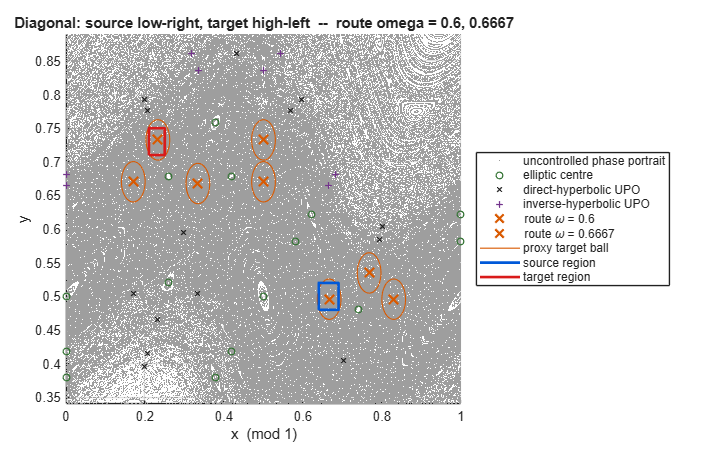

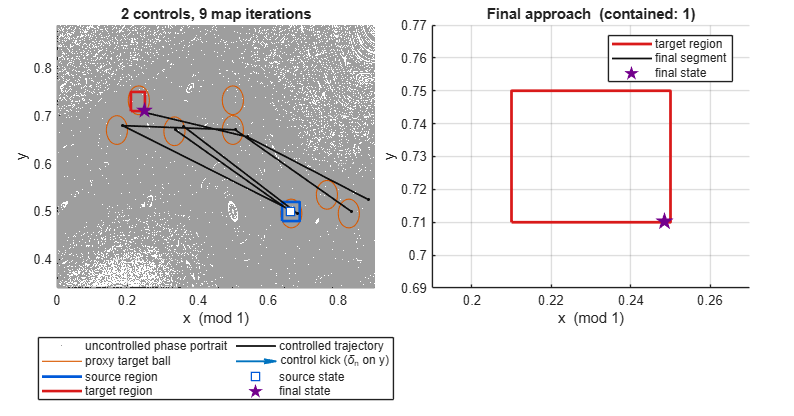

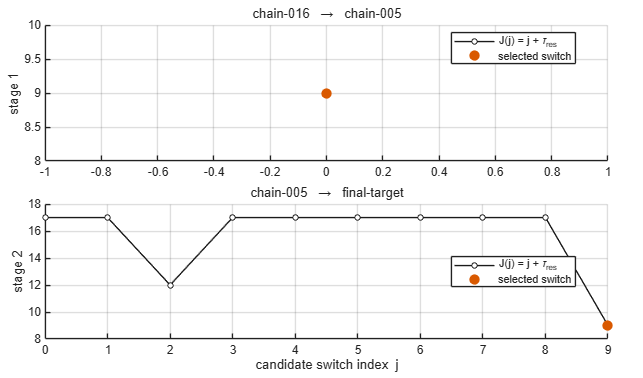

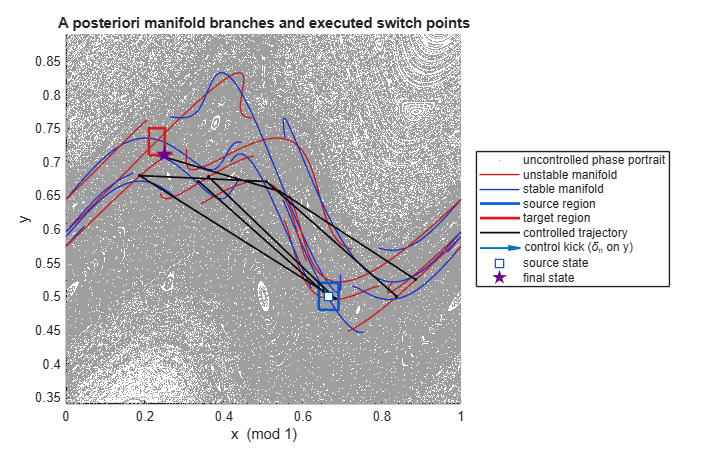


CASE: Horizontal: same transport band, half a period apart in x
  source rectangle  x=[0.315, 0.355]  y=[0.28, 0.32]
  target rectangle  x=[0.815, 0.855]  y=[0.28, 0.32]
  budgets  nForward<=16  nBackward<=16  tau<=30
route: empty rotation bracket over y in (0.3, 0.3)
       no intermediate resonance -- single forward-backward step

---- deterministic targeting summary: horizontal ----
target reached: 1
final containment: 1
source rectangle: x=[0.315, 0.355], y=[0.28, 0.32]
target rectangle: x=[0.815, 0.855], y=[0.28, 0.32]
selected target lift: 0
transport direction: +1
k: 1.25
control amplitude: 0.003
iteration budget: nForward<=16, nBackward<=16, tau<=30
maxPeriod: 5
route rotation numbers: (empty bracket, single forward-backward step)
skipped proxies: (none)
number of applied controls: 1
executed map iterations: 27
final state: [6.82553022122, 0.28]
max

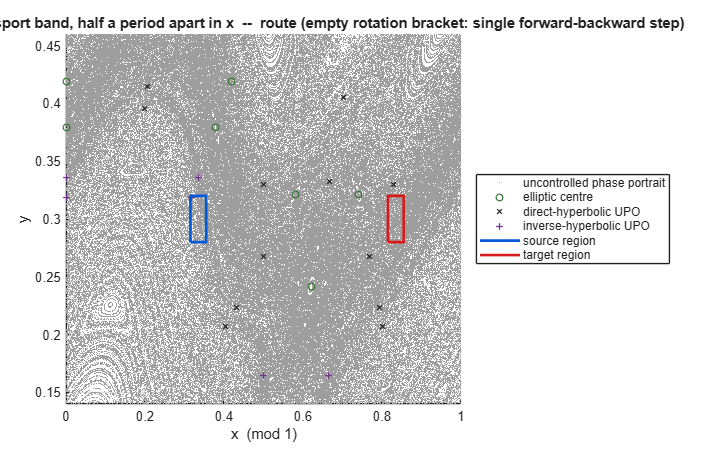

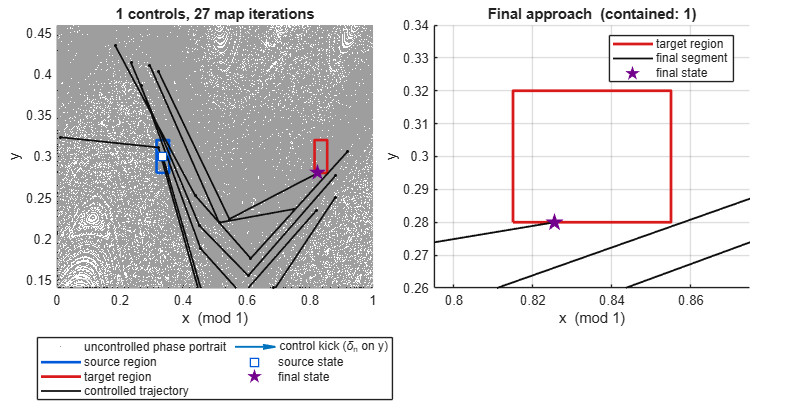


CASE: Vertical: same x-band, transport across three resonances
  source rectangle  x=[0.425, 0.465]  y=[0.4, 0.44]
  target rectangle  x=[0.425, 0.465]  y=[0.7, 0.74]
  budgets  nForward<=16  nBackward<=14  tau<=30
route rotation numbers: [0.5 0.6 0.666667]

---- deterministic targeting summary: vertical ----
target reached: 1
final containment: 1
source rectangle: x=[0.425, 0.465], y=[0.4, 0.44]
target rectangle: x=[0.425, 0.465], y=[0.7, 0.74]
selected target lift: 0
transport direction: +1
k: 1.25
control amplitude: 0.003
iteration budget: nForward<=16, nBackward<=14, tau<=30
maxPeriod: 5
route rotation numbers: [0.5 0.6 0.666667]
skipped proxies: chain-002
number of applied controls: 3
executed map iterations: 34
final state: [18.4450878185, 0.699999999029]
maximum applied abs(control): 0.00249182818782  (bound 0.003)
maximum intersection residual: 4.77

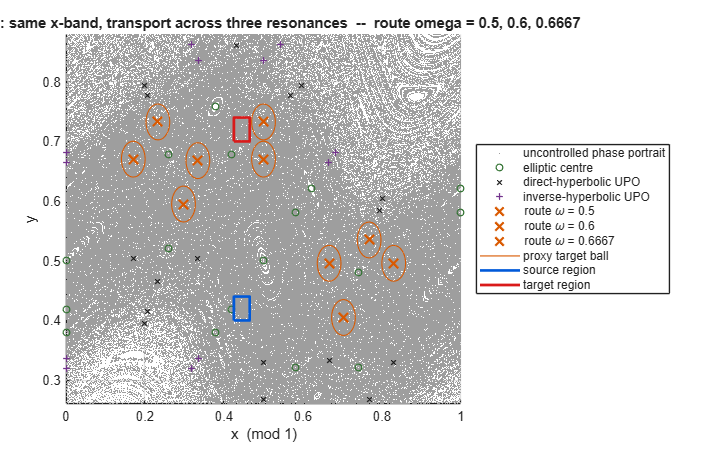

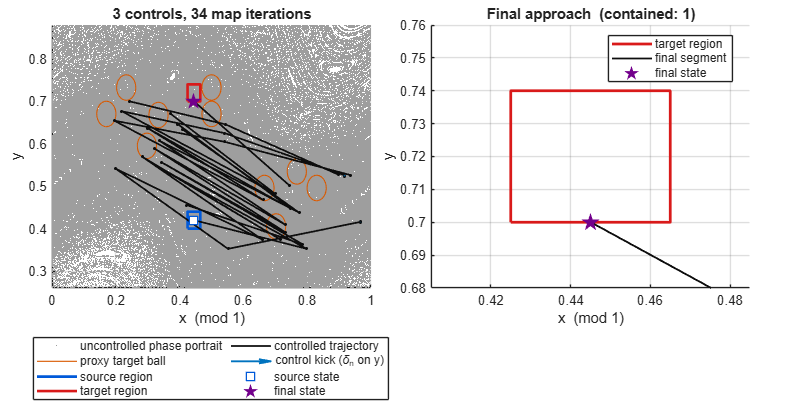

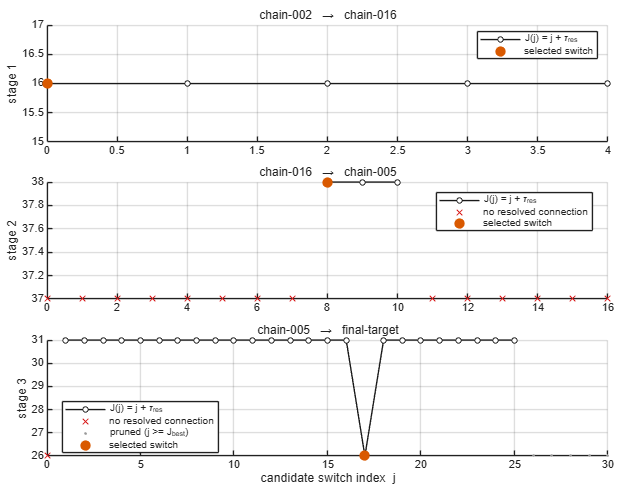

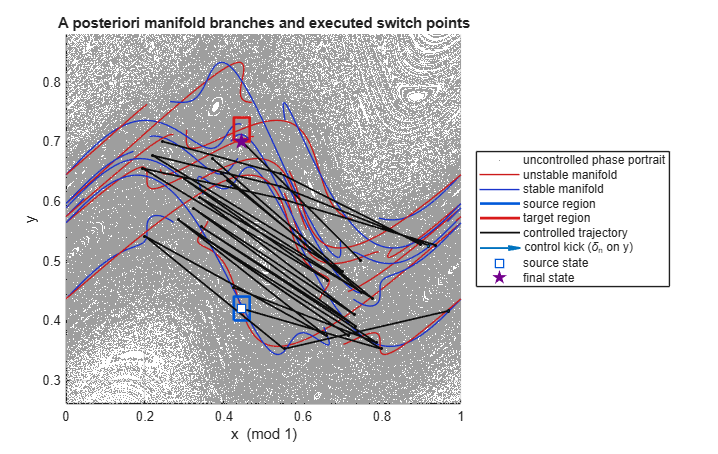


================ CASE COMPARISON ================
      caseName                               caseLabel                             sourceX    sourceY    targetX    targetY        routeOmegas        proxyCount    numberOfControls    totalIterations    maxAbsControl    totalAbsControl    controlBound    finalX    finalY     finalContainment    targetReached    maxIntersectionResidual    maxConsistencyError    allMinimaCertified    unresolvedSplits    failureCategory    runtimeSeconds
    ____________    ___________________________________________________________    <s

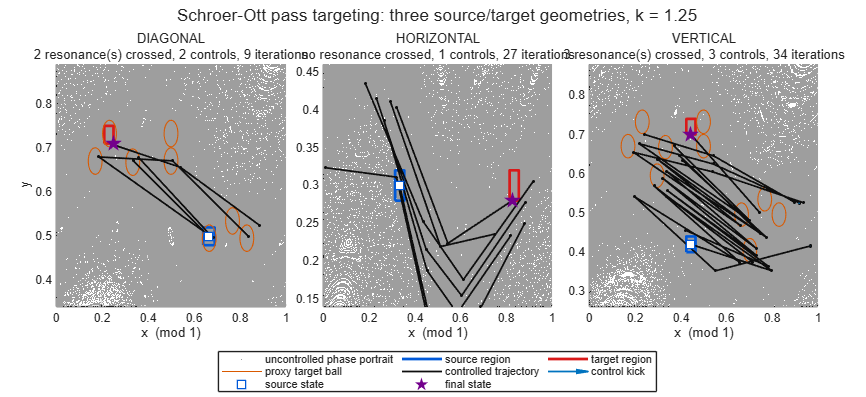

study = so_run_all_cases('Plot', true, 'Save', true, 'Verbose', true);

disp(study.comparison);

      caseName                               caseLabel                             sourceX    sourceY    targetX    targetY        routeOmegas        proxyCount    numberOfControls    totalIterations    maxAbsControl    totalAbsControl    controlBound    finalX    finalY     finalContainment    targetReached    maxIntersectionResidual    maxConsistencyError    allMinimaCertified    unresolvedSplits    failureCategory    runtimeSeconds
    ____________    ___________________________________________________________    _______    _______ 

Read the comparison table for three things. targetReached should be true in every row. maxAbsControl must never exceed controlBound. And maxConsistencyError should sit at machine precision: that column is the check that the trajectory plotted is the trajectory the solver planned, recomputed independently from the recorded controls rather than taken on trust.

## Validation I: The Fifty-Source Ensemble

This is the robustness statement the paper itself makes about Figure 3: "For 50 source points chosen at random in the gray source rectangle, the controlled trajectories reached the target rectangle after 125 to 132 iterations, while the uncontrolled transport times varied greatly between 1119 and 3.77e6 steps."

Two quantities are recorded per trial, and the second is what gives the first its meaning. The controlled iteration count should have a narrow spread, which is the claim that transfer time is set by the phase-space structure rather than by the particular initial condition. The uncontrolled first-passage time from the same point should be larger by orders of magnitude and wildly variable, which is what the control buys. Uncontrolled times are measured for all fifty sources simultaneously as a vector iteration, which is what makes a multi-million-step cap affordable.

On comparability, plainly. The ensemble runs on this build's diagonal geometry, not on the paper's digitised Figure-3 rectangles, so the iteration counts here are not comparable to 125-132: a different source, target and route give a different transfer time. What is comparable is the shape of the claim. The earlier attempt at the literal Figure-3 ensemble, in the schroer_ott_targeting folder, returned zero successes out of fifty, every trial hitting a 120 second cap on the seven-resonance route, and that case is not attempted here.


Enumerating periodic orbits for the ensemble...
  trial  1/50  source (0.6506, 0.5098)  target reached                controlled iterations =    22  [72.8 s]
  trial  2/50  source (0.6530, 0.5163)  target reached                controlled iterations =    12  [8.2 s]
  trial  3/50  source (0.6612, 0.5178)  target reached                controlled iterations =     4  [1.5 s]
  trial  4/50  source (0.6760, 0.5132)  target reached                controlled iterations =     7  [8.3 s]
  trial  5/50  source (0.6746, 0.4902)  FAILED: provisional_connection_failed  controlled iterations =    --  [7.6 s]
  trial  6/50  source (0.6764, 0.4819)  FAILED: provisional_connection_failed  controlled iterations =    --  [8.5 s]
  trial  7/50  source (0.6544, 0.4938)  FAILED: all_switch_probes_failed  controlled iterations =    --  [7.2 s]
  trial  8/50  source (0.6527, 0.4890)  FAILED: all_switch_probes_failed  controlled iterations =    --  [8.8 s]
  trial  9/50  source (0.6880, 0.5028)  target reach

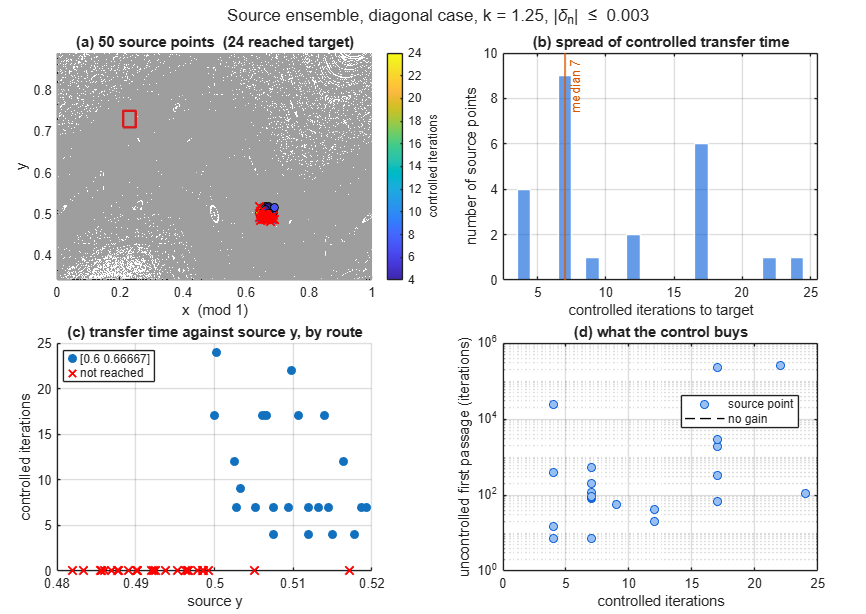

ensemble = so_run_source_ensemble('Case', 'diagonal', 'TrialCount', 50, ...
    'Uncontrolled', true, 'Plot', true, 'Save', true, 'Verbose', true);

disp(ensemble.summary);

    attempts    successes    successFraction    minIterations    maxIterations    meanIterations    medianIterations    stdIterations    iqrIterations                         allIterationCounts                          minUncontrolled    maxUncontrolled    medianUncontrolled    medianSpeedupFactor
    ________    _________    _______________    _____________    _____________    ______________    ________________    _____________    _____________    _____________________________________________________________    _______________    _______________    <s

Panel (c) of the ensemble figure repays attention. Sources drawn below $y = 0.5$ pick up the $\omega = 1/2$ resonance in their bracket and take a three-resonance route; those above it take a two-resonance route. The transfer time tracks the route, not the initial condition within a route, which is precisely the paper's point about transfer times being determined by the phase-space structure.

## Validation II: Additive Noise

From Section IV of the paper: "We studied targeting the standard map under the influence of small additive noise with amplitudes ranging up to $10^{-2} \times \delta$ at each iteration. Without any change to our targeting scheme, all trajectories reached the target."

Here $\delta$ is the full length of the admissible control segment, $2 \times 0.003 = 0.006$, so the published level is $\sigma = 6 \times 10^{-5}$ per iteration. Noise enters the momentum update, the same place the control does:


$$y_{n+1} = y_n - \frac{k}{2\pi}\sin(2\pi x_n) + \delta_n + \eta_n, \qquad \eta_n \sim \mathcal{N}(0, \sigma^2)$$


The test is deliberately the strict one. The deterministic control schedule is replayed open loop, with the controls and the iteration counts held fixed and never recomputed. The paper's claim is survival without any change to the scheme, and that is what this measures. Its own remedy for larger noise is to repeat the forward-backward procedure every few steps; a closed-loop implementation would therefore survive more noise than this test allows. Open-loop replay failing earlier is the point, not a defect.

Several amplitudes are swept rather than only the published one, because a single level that happens to pass says less than a curve showing where the scheme starts to break. The level $\sigma = 0$ is included as a control: it must reproduce the deterministic endpoint exactly, which also verifies that the replay itself is faithful.

  sigma =        0 (     0 x delta):  40/ 40 contained, median endpoint shift 0
  sigma =    6e-06 ( 0.001 x delta):  40/ 40 contained, median endpoint shift 0.000119
  sigma =    6e-05 (  0.01 x delta):  17/ 40 contained, median endpoint shift 0.00119
  sigma =   0.0006 (   0.1 x delta):   2/ 40 contained, median endpoint shift 0.0123

================ NOISE VALIDATION (diagonal) ================
delta = 0.006, schedule replayed open loop over 9 iterations
zero-noise replay reproduces the deterministic endpoint to 0
    sigmaOverDelta    sigma     realisations    containedCount    containedFraction    minDisplacement    medianDisplacement    maxDisplacement    stdDisplacement
    ______________    ______    ____________    ______________    _________________</

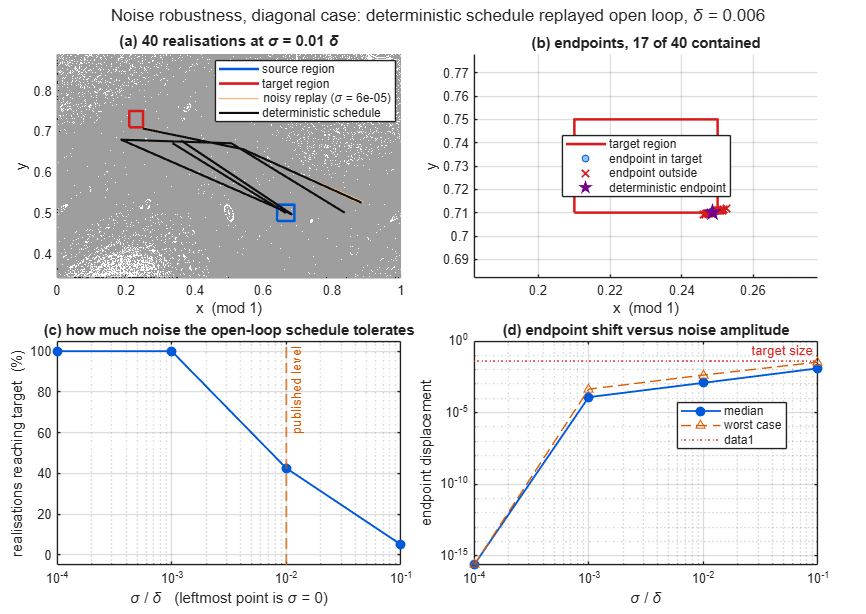

  sigma =        0 (     0 x delta):  40/ 40 contained, median endpoint shift 0
  sigma =    6e-06 ( 0.001 x delta):   3/ 40 contained, median endpoint shift 0.0217
  sigma =    6e-05 (  0.01 x delta):   0/ 40 contained, median endpoint shift 0.125
  sigma =   0.0006 (   0.1 x delta):   0/ 40 contained, median endpoint shift 0.404

================ NOISE VALIDATION (horizontal) ================
delta = 0.006, schedule replayed open loop over 27 iterations
zero-noise replay reproduces the deterministic endpoint to 0
    sigmaOverDelta    sigma     realisations    containedCount    containedFraction    minDisplacement    medianDisplacement    maxDisplacement    stdDisplacement
    ______________    ______    ____________    ______________    _________________

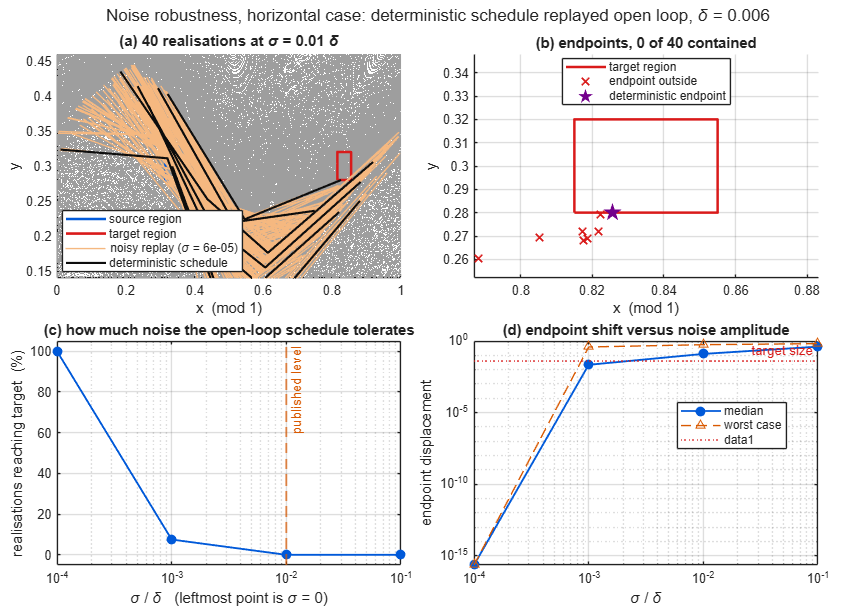

  sigma =        0 (     0 x delta):  40/ 40 contained, median endpoint shift 0
  sigma =    6e-06 ( 0.001 x delta):  20/ 40 contained, median endpoint shift 0.00639
  sigma =    6e-05 (  0.01 x delta):   2/ 40 contained, median endpoint shift 0.363
  sigma =   0.0006 (   0.1 x delta):   0/ 40 contained, median endpoint shift 0.289

================ NOISE VALIDATION (vertical) ================
delta = 0.006, schedule replayed open loop over 34 iterations
zero-noise replay reproduces the deterministic endpoint to 0
    sigmaOverDelta    sigma     realisations    containedCount    containedFraction    minDisplacement    medianDisplacement    maxDisplacement    stdDisplacement
    ______________    ______    ____________    ______________    _________________

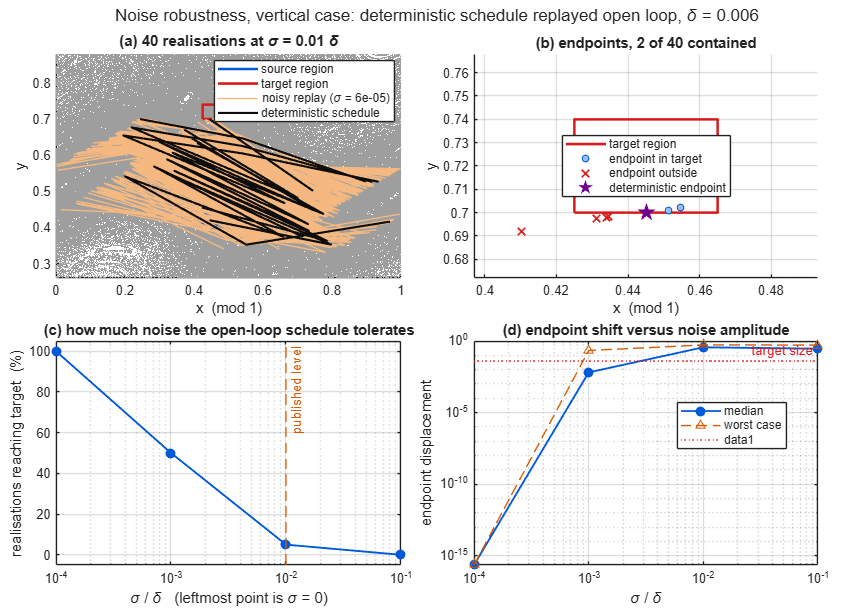

noise = cell(size(study.results));
for i = 1:numel(study.results), noise{i} = so_run_noise_validation(study.results{i}, 'Realisations', 40, 'Plot', true, 'Save', true, 'Verbose', true);
end

## Independent Connection Verification and Self-Checks

so_multistage_targeting records result.executionSegments: for every applied control, the state immediately before and after the kick, the number of iterations, and the replayed path. The fundamental build could not report this, and it is what makes the control kicks drawable as arrows, the noise replay possible, and execution_segments.csv meaningful.

The strongest check in the suite re-derives the whole trajectory from the recorded controls alone, using nothing the solver stored, then compares the endpoint against the reported one and against target containment. Two further checks are worth naming: the indexed polyline-intersection backend is compared against the brute-force reference implementation, so the spatial index cannot silently lose a crossing; and the source and target centres of all three cases are asserted to be chaotic.

testResults = test_schroer_ott_reconciled('Full', true);

  [pass] test_map_inverse_roundtrip                 max round-trip error 3.14e-16
  [pass] test_area_preservation                     max |det J - 1| = 3.33e-16
  [pass] test_wrap_helpers                          wrap, lift and cylinder-distance helpers agree
  [pass] test_periodic_orbits                       18 chains, worst residual 6.19e-14
  [pass] test_paper_fractions_present               all 7 Figure-3 fractions present and direct-hyperbolic
  [pass] test_rectangle_component                   rectangle boundary closes to 0.00e+00 and contains its samples
  [pass] test_circle_component                      circle radius exact to 5.90e-17
  [pass] test_curve_matches_direct_iteration        curve at n=5 matches direct iteration to 0.00e+00 (65 points)
  [pass] test_intersection_backends_agree           28 splits compared, 2 reference crossings all matched (0 extra)
  [pass] test_cylinder_wrappers                     cylinder wrappers agree with the lifted map modulo one period in 

disp(testResults);

    index                     test                      passed                                  message                                    seconds 
    _____    _______________________________________    ______    ____________________________________________________________________    _________

      1      "test_map_inverse_roundtrip"               true      "max round-trip error 3.14e-16"                                         0.0064967
      2      "test_area_preservation"                   true      "max |det J - 1| = 3.33e-16"                                            0.0029468
      3      "test_wrap_helpers"                        true      "wrap, lift and cylinder-distance helpers agree"                        0.0008766
      4      "test_periodic_orbits"                     true      "18 chains, worst resid

fprintf('%d of %d tests passed.\n', sum(testResults.passed), height(testResults));

18 of 18 tests passed.


## Published-Result Context

The numbers the paper reports for the standard map, for reference against what this folder produces:

- Figure 3, one trajectory: 125 iterations from the lower grey rectangle to the upper one, with eight controls, $|\delta_n| \le 0.003$.

- Fifty random source points: controlled transfer times 125 to 132, with 35 of 50 at or below 126; uncontrolled times between 1119 and $3.77 \times 10^6$.

- Bollt and Meiss, by recurrence targeting on the same configuration: shortest orbit 131 iterations, with others up to 251.

- At $k = 1.01$, where transport is far slower: 39 relevant resonances, $|\delta_n| \le 0.005$, a controlled trajectory of 597 iterations against 778 for Bollt and Meiss.

- Noise up to $10^{-2}\delta$: all trajectories reached the target, the longest recorded run being 154 iterations.

- Modelling error, controlling at $k = 1.25$ a system actually at $k = 1.249$, with retargeting every four steps: all trajectories reached the target, transfer times 126 to 216.

## Interpretation and Limitations

What this folder establishes. The forward-backward construction, the rotation-bracket route, the switching rule and the control bound together reproduce the paper's qualitative claims on the standard map. Transfers succeed with controls three orders of magnitude smaller than the phase-space scale. Transfer times are set by the route rather than by the initial condition. The schedule tolerates noise at the published amplitude. And the method degenerates correctly when there is no resonance to cross.

What it does not establish, stated plainly, because these bound what the figures can be used to claim:

- The paper's specific number, 125 to 132 iterations for its Figure-3 rectangles, is not reproduced. That case needs the full seven-resonance route, whose switch-probe search is far more expensive than the two- and three-resonance routes used here, and the earlier attempt at it timed out on every trial. The geometries in this build were chosen to be tractable and to exercise different route structures, not to match Figure 3 digit for digit.

- The rectangles are reproducible demonstration rectangles, not digitised paper coordinates.

- The periodic-orbit search is capped at period 5. Resonances of higher period are dense in a mixed phase space and are invisible to the route constructor, so the route is optimal over the resonances it can see, not over all of them.

- Minimality is certified, not assumed. Where timeMinimumCertified is false, the reported time is the minimum over the resolved search domain only.

- The noise test is open loop, as described above.

- The final target of the diagonal case contains the $\omega = 2/3$ phase point (0.2326, 0.7326), so its last leg costs zero iterations: the orbit is already there once the proxy is reached. This is inherited from the original demonstration and is faithful to the paper's practice of targeting a ball around each resonance's unstable periodic orbit, but it does mean the diagonal total is not a fair measure of a final approach. The horizontal and vertical cases both solve a genuine final leg.

## Reproducibility Summary

Every random draw in this document is seeded. The orbit catalogue is enumerated once and shared by the three cases, so they are provably working from identical periodic-orbit data. Outputs, tables and figures are written under the outputs directory, one subdirectory per case.

reproTable = table( ...
    cfg.k, cfg.controlAmplitude, cfg.orbit.maxPeriod, cfg.proxyTargetRadius, ...
    cfg.randomSeed, cfg.ensemble.randomSeed, cfg.noise.randomSeed, ...
    string(fullfile(pwd, 'outputs')), ...
    'VariableNames', {'k', 'ControlBound', 'MaxPeriod', 'ProxyRadius', ...
    'ConfigSeed', 'EnsembleSeed', 'NoiseSeed', 'OutputDirectory'});
disp(reproTable);

     k      ControlBound    MaxPeriod    ProxyRadius    ConfigSeed    EnsembleSeed    NoiseSeed                                             OutputDirectory                                         
    ____    ____________    _________    ___________    __________    ____________    __________    ________________________________________________________________________________________________

    1.25       0.003            5           0.03            1             1729        3.1416e+05    "C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\schroer_ott_reconciled\outputs"



To reproduce everything in one call, without stepping through this document, run main_schroer_ott_reconciled. For a fast pass that touches every code path, run it with reduced counts:

% main_schroer_ott_reconciled('EnsembleTrials', 3, 'Realisations', 10)

function plot_upo_catalogue_and_stability(catalogue, cfg)
figure('Color', 'w', 'Units', 'centimeters', 'Position', [2 2 28 12]);
layout = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
classNames = {'direct-hyperbolic', 'inverse-hyperbolic', 'elliptic'};
classLabels = {'direct-hyperbolic UPO', 'inverse-hyperbolic UPO', 'elliptic centre'};
classMarkers = {'x', '+', 'o'};
classColours = {[0.85 0.10 0.10], [0.45 0.20 0.55], [0.00 0.45 0.75]};

ax = nexttile(layout, 1);
hold(ax, 'on');
so_plot_phase_background(ax, cfg, [-0.05 1.05], false);
for c = 1:numel(classNames)
    shown = false;
    for i = 1:numel(catalogue.chains)
        if ~strcmp(catalogue.chains(i).classification, classNames{c}), continue; end
        p = catalogue.chains(i).pointsCylinder;
        if shown
            legendArgs = {'HandleVisibility', 'off'};
        else
            legendArgs = {'DisplayName', classLabels{c}};
            shown = true;
        end
        plot(ax, p(1, :), p(2, :), classMarkers{c}, 'Color', classColours{c}, ...
            'MarkerSize', 6, 'LineWidth', 1.1, legendArgs{:});
    end
end
axis(ax, [0 1 -0.05 1.05]);
xlabel(ax, 'x  (mod 1)'); ylabel(ax, 'y');
title(ax, '(a) Periodic-orbit catalogue on the mixed phase space');
grid(ax, 'on'); legend(ax, 'Location', 'northeast'); hold(ax, 'off');

ax = nexttile(layout, 2);
hold(ax, 'on');
patch(ax, [0 1 1 0], [-2 -2 2 2], [0.85 0.94 0.98], ...
    'EdgeColor', 'none', 'DisplayName', 'elliptic regime: |tr M| < 2');
yline(ax, 2, 'k--', 'HandleVisibility', 'off');
yline(ax, -2, 'k--', 'HandleVisibility', 'off');
for c = 1:numel(classNames)
    mask = strcmp({catalogue.chains.classification}, classNames{c});
    scatter(ax, [catalogue.chains(mask).omega], [catalogue.chains(mask).trace], ...
        54, classColours{c}, classMarkers{c}, 'LineWidth', 1.4, ...
        'DisplayName', classLabels{c});
end
xlabel(ax, 'rotation number \omega = m/p'); ylabel(ax, 'monodromy trace tr M');
title(ax, '(b) Stable and unstable classification regimes');
xlim(ax, [0 1]); grid(ax, 'on'); legend(ax, 'Location', 'best'); hold(ax, 'off');
title(layout, 'Standard-map periodic orbits at k = 1.25');
end

function plot_representative_manifolds(catalogue, cfg)
mask = strcmp({catalogue.chains.classification}, 'direct-hyperbolic') & ...
    abs([catalogue.chains.omega] - 1/2) < 1e-12;
route.chains = catalogue.chains(find(mask, 1));
manifolds = so_compute_diagnostic_manifolds(route, cfg);

figure('Color', 'w', 'Units', 'centimeters', 'Position', [2 2 19 12]);
ax = axes; hold(ax, 'on');
so_plot_phase_background(ax, cfg, [0.35 0.75], false);
shownStable = false; shownUnstable = false;
for i = 1:numel(manifolds)
    pts = so_to_cylinder(manifolds(i).curve.pointsLifted);
    pts(:, [false, abs(diff(pts(1, :))) > 0.5]) = NaN;
    if manifolds(i).branchType == "unstable"
        colour = [0.85 0.10 0.10];
        if shownUnstable, args = {'HandleVisibility', 'off'};
        else, args = {'DisplayName', 'unstable manifold'}; shownUnstable = true; end
    else
        colour = [0.10 0.25 0.75];
        if shownStable, args = {'HandleVisibility', 'off'};
        else, args = {'DisplayName', 'stable manifold'}; shownStable = true; end
    end
    plot(ax, pts(1, :), pts(2, :), '-', 'Color', colour, 'LineWidth', 0.9, args{:});
end
p = route.chains.pointsCylinder;
plot(ax, p(1, :), p(2, :), 'kx', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'direct-hyperbolic UPO, \omega = 1/2');
axis(ax, [0 1 0.35 0.75]);
xlabel(ax, 'x  (mod 1)'); ylabel(ax, 'y');
title(ax, 'Stable and unstable branches of a representative hyperbolic UPO');
grid(ax, 'on'); legend(ax, 'Location', 'northeast'); hold(ax, 'off');
end